# comparing basic demographics for the TNG50 andTNG100 on a similar samlple 

## perliminaries

global DEFAULT_MATFILE_DIR
global DEFAULT_PRINTOUT_DIR
colors=brewermap(9,'Set1');
%figPos=[1043         181         840         733];
figPos=[1169         181         714         573];
outdir=[DEFAULT_PRINTOUT_DIR '/jellyfish/paper'];
%printFlag=true;

 axFont=18;
 legFont=20;
 labFont=20;

## load data


    % load object table
    load([DEFAULT_MATFILE_DIR '\cosmic_jellyfish_objectTable.mat']);
    objectCJF=objectTable;
    % load galaxy properties
    load([DEFAULT_MATFILE_DIR '\jf_galProperties_CJF.mat']);
    
   printFlag=false;

## add additional data fields

  %  massRatio=galProps.galStellarMass./galProps.hostM200c;
    zreds=round(illustris.utils.snap2redshift(galProps.snap),2);

    % define JF
    
    threshJF=0.8;
    fprintf('JF Threshold set to %i and above. \n', threshJF);

JF Threshold set to 8.000000e-01 and above. 


    
    maskJF=objectCJF.scoreWeighted>=0.8;
    maskJFraw=objectCJF.scoreRaw>=0.8;
    %maskNJF=objectCJF.scoreWeighted<=0.2;
    
    % list snaps and redshifts
    snaps=unique(objectCJF.snap);
    redshifts=round(illustris.utils.snap2redshift(snaps),2);


    %mm=galProps.hostM200c<1e11 & maskJF';
    %ind=find(mm); index of 3 weird objects
    %maskJF_full=maskJF;
    %maskJF(mm)=false;
    
    mask100=objectCJF.sim=="TNG100";
    mask50=~mask100;

## generate TNG50 in the TNG100 snap and mass range

     snaps100=unique(objectCJF.snap(mask100));
       
     mskMass=log10(galProps.galStellarMass)'>=9.5;
     snapMask=false(size(objectCJF.snap));
     for i=1:length(snaps100)
         snapMask=snapMask | objectCJF.snap==snaps100(i);
     end
    


## plot some general info about the sample - raw scores 

if 1==1
    nObject=height(objectCJF);
    fprintf('Total number of objects = %i \n',nObject);
    fprintf('Total number of JF = %i (%4.2f %%) \n',sum(maskJFraw),sum(maskJFraw)/nObject*100);
    
    
    fprintf('TNG100 number of objects = %i (%4.2f %%) \n',sum(mask100),sum(mask100)/nObject*100);
    fprintf('TNG50 number of objects = %i (%4.2f %%) \n',sum(mask50),sum(mask50)/nObject*100);
    
    fprintf('TNG100 number of JFs = %i (%4.2f %%) \n',sum(maskJFraw & mask100),sum(maskJFraw & mask100)/sum(mask100)*100);
    fprintf('TNG50 number of JFs = %i (%4.2f %%) \n',sum(maskJFraw & mask50),sum(maskJFraw & mask50)/sum(mask50)*100);
    
    fprintf('TNG50 number of objects in TNG100 mass range = %i (%4.2f %%) \n',sum(mask50 & mskMass ),sum(mask50 & mskMass )/sum(mask50)*100);
    fprintf('TNG50 number of objects in TNG100 snap range = %i (%4.2f %%) \n',sum(mask50 & snapMask),sum(mask50 & snapMask )/sum(mask50)*100);
    fprintf('TNG50 number of objects in TNG100 snap & mass range = %i (%4.2f %%) \n',sum(mask50 & snapMask & mskMass),sum(mask50 & snapMask & mskMass)/sum(mask50)*100);
    
    fprintf('TNG50  JFs in TNG100 mass range = %i (%4.2f %%) \n',sum(maskJFraw & mask50 & mskMass),sum(maskJFraw & mask50 & mskMass)/sum(mask50 & mskMass)*100);
    fprintf('TNG50  JFs in TNG100 snap range = %i (%4.2f %%) \n',sum(maskJFraw & mask50 & snapMask),sum(maskJFraw & mask50 & snapMask)/sum(mask50 & snapMask)*100);
    fprintf('TNG50  JFs in TNG100 mass and snap range = %i (%4.2f %%) \n',sum(maskJFraw & mask50 & mskMass & snapMask),sum(maskJFraw & mask50 & mskMass & snapMask)/sum(mask50 & mskMass & snapMask)*100);

end

Total number of objects = 80704 


Total number of JF = 4553 (5.64 %) 


TNG100 number of objects = 27094 (33.57 %) 


TNG50 number of objects = 53610 (66.43 %) 


TNG100 number of JFs = 846 (3.12 %) 


TNG50 number of JFs = 3707 (6.91 %) 


TNG50 number of objects in TNG100 mass range = 14589 (27.21 %) 


TNG50 number of objects in TNG100 snap range = 13959 (26.04 %) 


TNG50 number of objects in TNG100 snap & mass range = 3550 (6.62 %) 


TNG50  JFs in TNG100 mass range = 796 (5.46 %) 


TNG50  JFs in TNG100 snap range = 762 (5.46 %) 


TNG50  JFs in TNG100 mass and snap range = 169 (4.76 %) 


## plot some general info about the sample - adjusted scores 

if 1==1
    nObject=height(objectCJF);
    fprintf('Total number of objects = %i \n',nObject);
    fprintf('Total number of JF = %i (%4.2f %%) \n',sum(maskJF),sum(maskJF)/nObject*100);
    
    
    fprintf('TNG100 number of objects = %i (%4.2f %%) \n',sum(mask100),sum(mask100)/nObject*100);
    fprintf('TNG50 number of objects = %i (%4.2f %%) \n',sum(mask50),sum(mask50)/nObject*100);
    
    fprintf('TNG100 number of JFs = %i (%4.2f %%) \n',sum(maskJF & mask100),sum(maskJF & mask100)/sum(mask100)*100);
    fprintf('TNG50 number of JFs = %i (%4.2f %%) \n',sum(maskJF & mask50),sum(maskJF & mask50)/sum(mask50)*100);
    
    fprintf('TNG50 number of objects in TNG100 mass range = %i (%4.2f %%) \n',sum(mask50 & mskMass ),sum(mask50 & mskMass )/sum(mask50)*100);
    fprintf('TNG50 number of objects in TNG100 snap range = %i (%4.2f %%) \n',sum(mask50 & snapMask),sum(mask50 & snapMask )/sum(mask50)*100);
    fprintf('TNG50 number of objects in TNG100 snap & mass range = %i (%4.2f %%) \n',sum(mask50 & snapMask & mskMass),sum(mask50 & snapMask & mskMass)/sum(mask50)*100);
    
    fprintf('TNG50  JFs in TNG100 mass range = %i (%4.2f %%) \n',sum(maskJF & mask50 & mskMass),sum(maskJF & mask50 & mskMass)/sum(mask50 & mskMass)*100);
    fprintf('TNG50  JFs in TNG100 snap range = %i (%4.2f %%) \n',sum(maskJF & mask50 & snapMask),sum(maskJF & mask50 & snapMask)/sum(mask50 & snapMask)*100);
    fprintf('TNG50  JFs in TNG100 mass and snap range = %i (%4.2f %%) \n',sum(maskJF & mask50 & mskMass & snapMask),sum(maskJF & mask50 & mskMass & snapMask)/sum(mask50 & mskMass & snapMask)*100);

end

Total number of objects = 80704 


Total number of JF = 5307 (6.58 %) 


TNG100 number of objects = 27094 (33.57 %) 


TNG50 number of objects = 53610 (66.43 %) 


TNG100 number of JFs = 1163 (4.29 %) 


TNG50 number of JFs = 4144 (7.73 %) 


TNG50 number of objects in TNG100 mass range = 14589 (27.21 %) 


TNG50 number of objects in TNG100 snap range = 13959 (26.04 %) 


TNG50 number of objects in TNG100 snap & mass range = 3550 (6.62 %) 


TNG50  JFs in TNG100 mass range = 874 (5.99 %) 


TNG50  JFs in TNG100 snap range = 815 (5.84 %) 


TNG50  JFs in TNG100 mass and snap range = 182 (5.13 %) 


## compare stellar mass and host distribution


myFigure('pos',figPos);
  
histogram(log10(galProps.hostM200c(mask100)),10:0.25:15,'normalization','probability')
hold on;
%histogram(log10(galProps.hostM200c(mask50)),10:0.25:15,'normalization','probability')
histogram(log10(galProps.hostM200c(mask50 & mskMass & snapMask)),10:0.25:15,'normalization','probability')
ylim([5e-5 2e-1])
set(gca,'Yscale','log','fontsize',axFont,'TickLabelInterpreter','latex');
legend(["TNG100", "TNG50", 'Match'],'location','northwest');

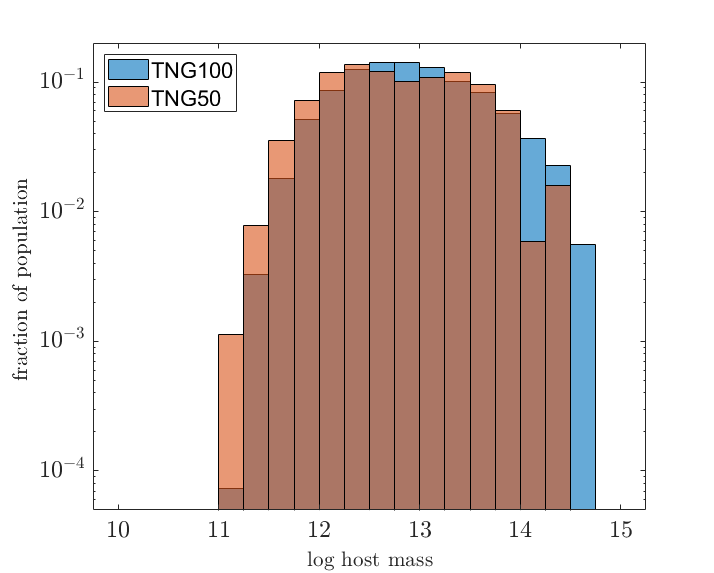

xlabelmine('log host mass');
ylabelmine('fraction of population ');



myFigure('pos',figPos);
  
histogram(log10(galProps.galStellarMass(mask100)),8:0.25:12.5,'normalization','probability')
hold on;
%histogram(log10(galProps.galStellarMass(mask50)),8:0.25:12.5,'normalization','probability')
histogram(log10(galProps.galStellarMass(mask50 & mskMass & snapMask)),8:0.25:12.5,'normalization','probability')
set(gca,'Yscale','log','fontsize',axFont,'TickLabelInterpreter','latex')
legend(["TNG100", "TNG50", 'Match'],'location','northwest');

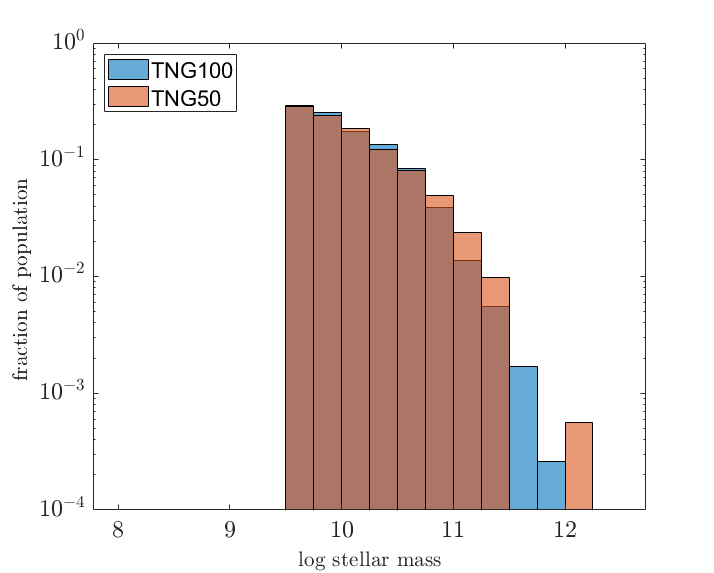

xlabelmine('log stellar  mass');
ylabelmine('fraction of population ');

## plot scores

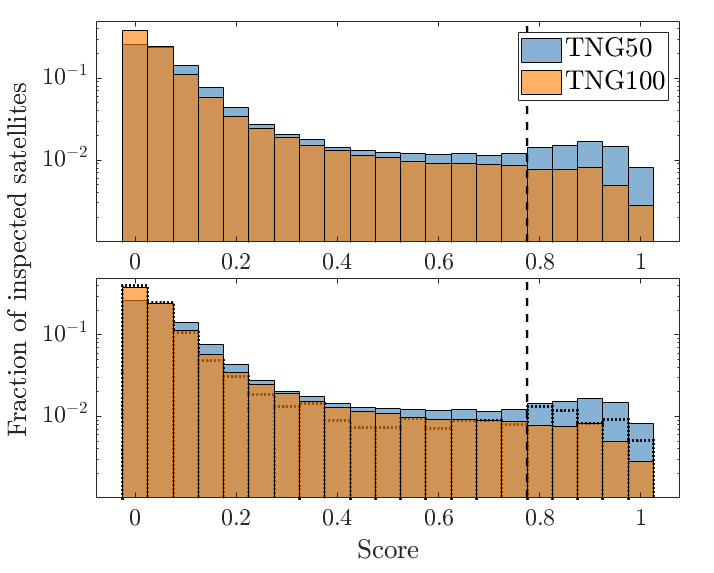


    bins=-0.025:0.05:1.025;
    
    % plot initial scores 
    myFigure('pos',figPos);
    %yl=[0.0 0.35];
    t=tiledlayout(2,1);
    nexttile
   
    yl2=[0.001 0.5];
    
    histogram(objectCJF.scoreRaw(mask50 ),bins,'normalization','probability','facecolor',colors(2,:));
    hold on
    
    histogram(objectCJF.scoreRaw(mask100),bins,'normalization','probability','facecolor',colors(5,:));
    plot(0.775.*ones(size(yl2)),yl2,'--k'  ,'linewidth',1.8)
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')

    
    
     legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',legFont)
    %legend("Full Sample",'Interpreter','latex','FontSize',legFont)
    %xlabelmine('Score');
    ylim(yl2)
    set(gca,'fontsize',axFont,'TickLabelInterpreter','latex')
    %ylabelmine('fraction of populaiton');
    %titlemine('All');
    
    nexttile
    
    histogram(objectCJF.scoreRaw(mask50),bins,'normalization','probability','facecolor',colors(2,:));
     hold on
    histogram(objectCJF.scoreRaw(mask50 & mskMass & snapMask ),bins,'linestyle',':','linewidth',2,'normalization','probability','facecolor','none','EdgeColor','k');
    
    
    
    
  
    histogram(objectCJF.scoreRaw(mask100),bins,'normalization','probability','facecolor',colors(5,:));
    
    %histogram(objectCJF.scoreRaw(mask50 ),bins,'normalization','probability','facecolor','none');
    
    
    
    plot(0.775.*ones(size(yl2)),yl2,'--k'  ,'linewidth',1.8)
    %legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',legFont)
    ylim(yl2)
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')
    xlabelmine('Score',20);
    %ylabelmine('fraction of populaiton');
    %titlemine('TNG50');
    
    ylabel(t,'Fraction of inspected satellites','fontsize',labFont,'interpreter','latex')
    t.TileSpacing='tight';
    t.Padding='compact';

    
    if printFlag
        fname='cjf_scoreHist_initial';
        printout_fig(gcf,fname,'pdfv','v','printoutdir',outdir);
    end

    

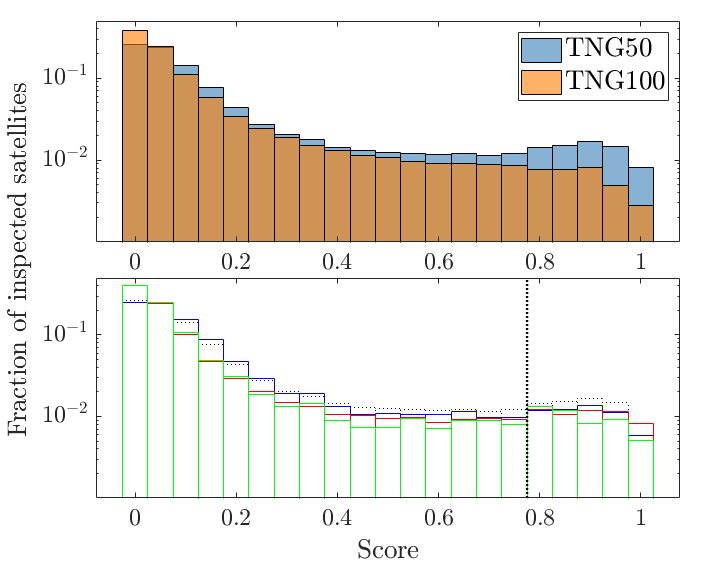

     bins=-0.025:0.05:1.025;
    
    % plot initial scores 
    myFigure('pos',figPos);
    %yl=[0.0 0.35];
    t=tiledlayout(2,1);
    nexttile
   
    yl2=[0.001 0.5];
    
    histogram(objectCJF.scoreRaw(mask50 ),bins,'normalization','probability','facecolor',colors(2,:));
    hold on
    
    histogram(objectCJF.scoreRaw(mask100),bins,'normalization','probability','facecolor',colors(5,:));
    
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')

    
    
     legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',legFont)
    %legend("Full Sample",'Interpreter','latex','FontSize',legFont)
    %xlabelmine('Score');
    ylim(yl2)
    set(gca,'fontsize',axFont,'TickLabelInterpreter','latex')
    %ylabelmine('fraction of populaiton');
    %titlemine('All');
    
    nexttile
    
    %histogram(objectCJF.scoreRaw(mask50 & mskMass & snapMask),bins,'normalization','probability','facecolor',colors(2,:));
    histogram(objectCJF.scoreRaw(mask50 ),bins,'linestyle',':','normalization','probability','facecolor','none','EdgeColor','k');
    
     hold on
    histogram(objectCJF.scoreRaw(mask50 & mskMass ),bins,'normalization','probability','facecolor','none','EdgeColor','b');
    histogram(objectCJF.scoreRaw(mask50 & snapMask),bins,'normalization','probability','facecolor','none','EdgeColor','r');
    histogram(objectCJF.scoreRaw(mask50 & mskMass & snapMask),bins,'normalization','probability','facecolor','none','EdgeColor','g');
    
  
    %histogram(objectCJF.scoreRaw(mask100),bins,'normalization','probability','facecolor',colors(5,:));
    
    %histogram(objectCJF.scoreRaw(mask50 ),bins,'normalization','probability','facecolor','none');
    
    
    
    plot(0.775.*ones(size(yl2)),yl2,':k'  ,'linewidth',1.8)
    %legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',legFont)
    ylim(yl2)
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')
    xlabelmine('Score',20);
    %ylabelmine('fraction of populaiton');
    %titlemine('TNG50');
    
    ylabel(t,'Fraction of inspected satellites','fontsize',labFont,'interpreter','latex')
    t.TileSpacing='tight';
    t.Padding='compact';

    
    if printFlag
        fname='cjf_scoreHist_initial';
        printout_fig(gcf,fname,'pdfv','v','printoutdir',outdir);
    end

    
    
    

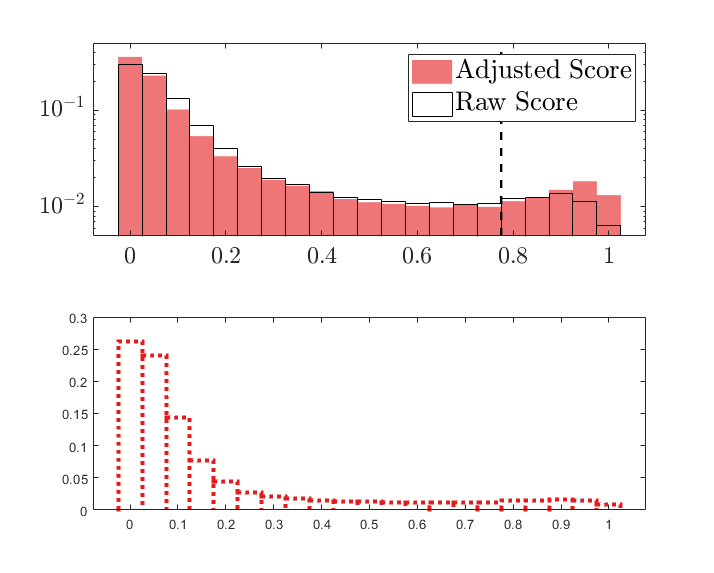

%colorss=brewermap(12,'Paired');
    hs=[];
    % plot weighted scores 
    myFigure('pos',figPos);
    yl=[0.005 0.5];
      t=tiledlayout(2,1);
      nexttile  %([2 1])
    histogram(objectCJF.scoreWeighted,bins,'normalization','probability',...
        'facecolor',colors(1,:),'edgecolor','none')
    hold on 
    
    histogram(objectCJF.scoreRaw,bins,'normalization','probability',...
        'facecolor','none','edgecolor','k')
    
    ylim(yl)
    hold on
    plot(0.775.*ones(size(yl2)),yl2,'--k'  ,'linewidth',1.8)
    legend(["Adjusted Score","Raw Score"] ,'Interpreter','latex','FontSize',legFont)
    %xlabelmine('Score');
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')
    %xlabelmine('Score',labFont);
    %ylabelmine('Fraction of inspected satellites',labFont);
    set(gca,'fontsize',axFont,'TickLabelInterpreter','latex')
    %ylabelmine('fraction of populaiton');
    %titlemine('All');
    
    nexttile
    hs1=histogram(objectCJF.scoreRaw(mask50),bins,'linestyle',':','linewidth',3,'normalization','probability','facecolor','none','EdgeColor',colors(1,:),'DisplayName','TNG50 Raw');

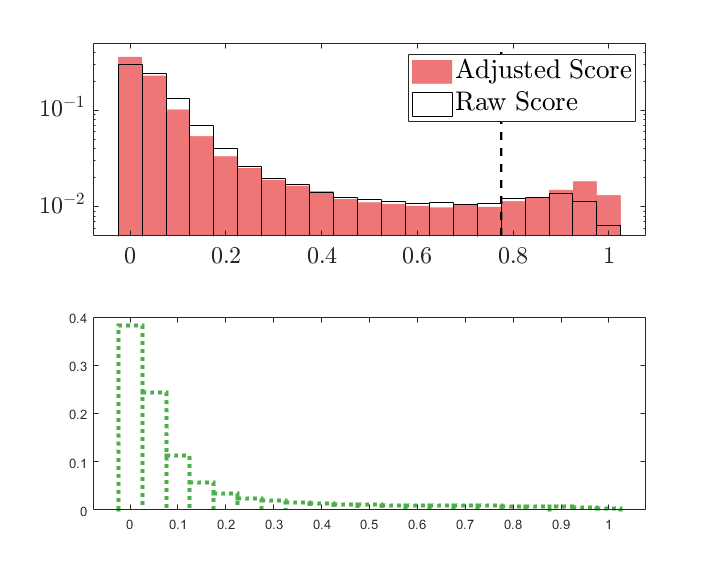

    b1=hs1.BinEdges;vb1=[hs1.Values hs1.Values(end)];
    hs2=histogram(objectCJF.scoreRaw(mask100),bins,'linestyle',':','linewidth',3,'normalization','probability','facecolor','none','EdgeColor',colors(3,:),'DisplayName','TNG100 Raw');

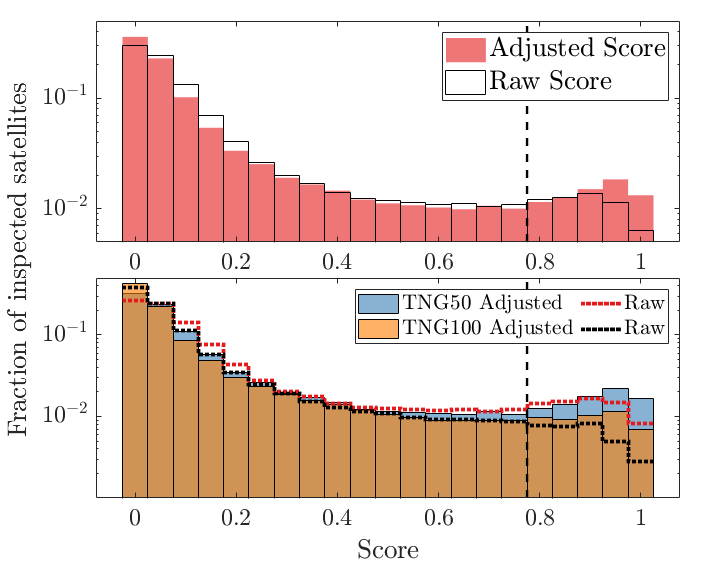

     b2=hs2.BinEdges;vb2=[hs2.Values hs2.Values(end)];
     
    hs(1)=histogram(objectCJF.scoreWeighted(mask50),bins,'normalization','probability','facecolor',colors(2,:),'DisplayName','TNG50 Adjusted');
    hold on
    % histogram(objectCJF.scoreWeighted(mask50 & mskMass & snapMask ),bins,'linestyle',':','linewidth',2,'normalization','probability','facecolor','none','EdgeColor','k');
    hs(2)=histogram(objectCJF.scoreWeighted(mask100),bins,'normalization','probability','facecolor',colors(5,:),'DisplayName','TNG100 Adjusted');

    hs(3)=stairs(b1,vb1,'linestyle',':','linewidth',2.8,'Color',colors(1,:),'DisplayName',' Raw');
    hs(4)=stairs(b2,vb2,'linestyle',':','linewidth',2.8,'Color','k','DisplayName',' Raw');
    
     %hs=histogram(objectCJF.scoreRaw(mask50),bins,'linestyle',':','linewidth',3,'normalization','probability','facecolor','none','EdgeColor',colors(4,:),'DisplayName','TNG50 Raw');
     %hs(4)=histogram(objectCJF.scoreRaw(mask100),bins,'linestyle',':','linewidth',3,'normalization','probability','facecolor','none','EdgeColor',colors(1,:),'DisplayName','TNG100 Raw');

     
    plot(0.775.*ones(size(yl2)),yl2,'--k'  ,'linewidth',1.8)
    legend(hs,'Interpreter','latex','FontSize',16,'NumColumns',2)
    ylim(yl2)
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')
    xlabelmine('Score',20);
    %ylabelmine('fraction of populaiton');
    %titlemine('TNG50');
    
    ylabel(t,'Fraction of inspected satellites','fontsize',labFont,'interpreter','latex')
    t.TileSpacing='tight';
    t.Padding='compact';

    if printFlag
        fname='cjf_scoreHist_weighted';
        printout_fig(gcf,fname,'pdfv','v','printoutdir',outdir);
    end
    
    

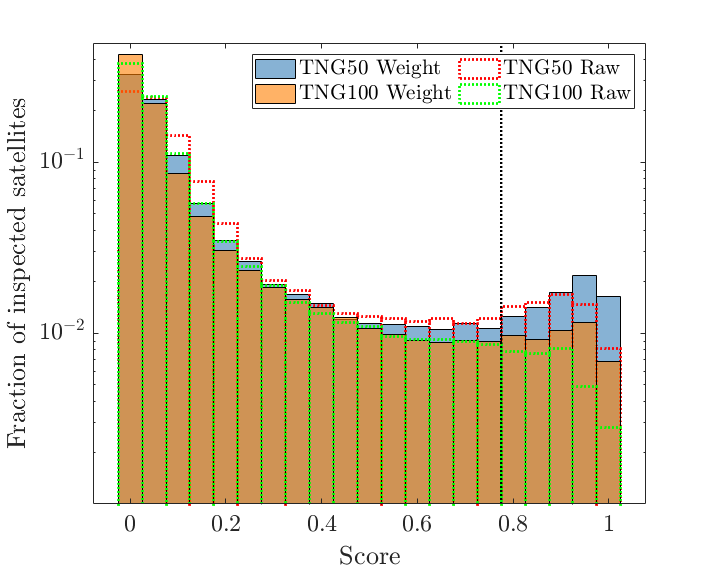

   
    % plot weighted scores 
    myFigure('pos',figPos);
    yl=[0.001 0.5];
%      t=tiledlayout(2,1);
%      nexttile
%    
hs=[];
      hs(1)=histogram(objectCJF.scoreWeighted(mask50),bins,'normalization','probability','facecolor',colors(2,:),'edgecolor','k','DisplayName','TNG50 Weight');
     hold on
     
      hs(3)=histogram(objectCJF.scoreRaw(mask50),bins,'linestyle',':','linewidth',2,'normalization','probability','facecolor','none','EdgeColor','r','DisplayName','TNG50 Raw');
       hs(2)=  histogram(objectCJF.scoreWeighted(mask100),bins,'normalization','probability','facecolor',colors(5,:),'edgecolor','k','DisplayName','TNG100 Weight');
    hs(4)=histogram(objectCJF.scoreRaw(mask100),bins,'linestyle',':','linewidth',2,'normalization','probability','facecolor','none','EdgeColor','g','DisplayName','TNG100 Raw');
    %hs(5)=histogram(objectCJF.scoreWeighted(mask50 & mskMass & snapMask ),bins,'linestyle','-.','linewidth',2,'normalization','probability','facecolor','none','EdgeColor','k','DisplayName','TNG50 comp');
    ylim(yl)
    hold on
    plot(0.775.*ones(size(yl)),yl,':k' ,'linewidth',1.8)
    legend(hs ,'Interpreter','latex','FontSize',16,'NumColumns',2)
    %xlabelmine('Score');
    set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')
    xlabelmine('Score',labFont);
    ylabelmine('Fraction of inspected satellites',labFont);
    set(gca,'fontsize',axFont,'TickLabelInterpreter','latex')

    %ylabelmine('fraction of populaiton');
    %titlemine('All');
    
%      nexttile
%     histogram(objectCJF.scoreWeighted(mask50),bins,'normalization','probability','facecolor',colors(2,:));
%      hold on
%     histogram(objectCJF.scoreWeighted(mask50 & mskMass & snapMask ),bins,'linestyle',':','linewidth',2,'normalization','probability','facecolor','none','EdgeColor','k');
%     
%        
%   
%     histogram(objectCJF.scoreWeighted(mask100),bins,'normalization','probability','facecolor',colors(5,:));
%     
%     %histogram(objectCJF.scoreRaw(mask50 ),bins,'normalization','probability','facecolor','none');
%     
%     
%     
%     plot(0.775.*ones(size(yl2)),yl2,'--k'  ,'linewidth',1.8)
%     %legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',legFont)
%     ylim(yl2)
%     set(gca,'Yscale','log','fontsize',axFont,'Ytick',[0.01 0.1],'TickLabelInterpreter','latex')
%     xlabelmine('Score',20);
%     %ylabelmine('fraction of populaiton');
%     %titlemine('TNG50');
%     
%     ylabel(t,'Fraction of inspected satellites','fontsize',labFont,'interpreter','latex')
%     t.TileSpacing='tight';
%     t.Padding='compact';

## Compare to Yun sample and TNG50 pilot

% generate a list of objects in the Yun sample

load([DEFAULT_MATFILE_DIR '/yun19_jellyfish_objectTable.mat'])
object100=objectTable;


load([DEFAULT_MATFILE_DIR '/jf_objectTable_TNG50.mat'])
load([DEFAULT_MATFILE_DIR '/jellyfishScores_TNG50.mat'])
object50=objectTable;


indCJF50=zeros(height(object50),1)-1;

for j=1:height(object50)
    subID=object50.subfind(j);
    snp=object50.snap(j);
    
    ind=find(objectCJF.snap==snp & objectCJF.subfind==subID & mask50);
    if ~isempty(ind)
        indCJF50(j)=ind;
    end
end

indMask50=indCJF50>0;

fprintf('Size of TNG50 pilot sample: %i \n',height(object50))

Size of TNG50 pilot sample: 3469 


fprintf('Number of objects in Pilot program found in CJF: %i \n',sum(indMask50) )

Number of objects in Pilot program found in CJF: 3466 


indCJF100=zeros(height(object100),1)-1; % indices in CJF object table of matched objects

for j=1:height(object100)
    subID=object100.subfind(j);
    snp=object100.snap(j);
    
    ind=find(objectCJF.snap==snp & objectCJF.subfind==subID & mask100);
    if ~isempty(ind)
        indCJF100(j)=ind;
    end
end

indMask100=indCJF100>0;

fprintf('Number of objects in yun+19 sample found in CJF: %i \n',sum(indMask100) )

Number of objects in yun+19 sample found in CJF: 2142 


fprintf('percentage of objects in yun+19 sample found in CJF: %i \n',100.*sum(indMask100)./sum(mask100) )

percentage of objects in yun+19 sample found in CJF: 7.905809e+00 


## how many TNG100 galaxies who changed their scores are in the Yun sample?

newJF100=objectCJF.scoreRaw<0.8 & objectCJF.scoreWeighted>=0.8 & mask100;
newNJF100=objectCJF.scoreRaw>=0.8 & objectCJF.scoreWeighted<0.8 & mask100;

fprintf("no. of CJF TNG100 gals who became JF after adjustment: %i",sum(newJF100))

no. of CJF TNG100 gals who became JF after adjustment: 329

fprintf("no. of CJF TNG100 gals who became NJF after adjustment: %i",sum(newNJF100))

no. of CJF TNG100 gals who became NJF after adjustment: 12


indx=indCJF100(indCJF100>0);

newJF100Yun=objectCJF.scoreRaw(indx)<0.8 & objectCJF.scoreWeighted(indx)>=0.8 & mask100(indx);
newNJF100Yun=objectCJF.scoreRaw(indx)>=0.8 & objectCJF.scoreWeighted(indx)<0.8 & mask100(indx);

fprintf("no. of CJF TNG100 gals who became JF after adjustment from Yun19: %i",sum(newJF100Yun))

no. of CJF TNG100 gals who became JF after adjustment from Yun19: 245

fprintf("no. of CJF TNG100 gals who became NJF after adjustment from Yun19: %i",sum(newNJF100Yun))

no. of CJF TNG100 gals who became NJF after adjustment from Yun19: 4

## how many TNG50 galaxies who changed their scores are in the pilot sample?

newJF50=objectCJF.scoreRaw<0.8 & objectCJF.scoreWeighted>=0.8 & mask50;
newNJF50=objectCJF.scoreRaw>=0.8 & objectCJF.scoreWeighted<0.8 & mask50;

fprintf("no. of CJF TNG50 gals who became JF after adjustment: %i",sum(newJF50))

no. of CJF TNG50 gals who became JF after adjustment: 501

fprintf("no. of CJF TNG50 gals who became NJF after adjustment: %i",sum(newNJF50))

no. of CJF TNG50 gals who became NJF after adjustment: 64


indx=indCJF50(indCJF50>0);

newJF50Pilot=objectCJF.scoreRaw(indx)<0.8 & objectCJF.scoreWeighted(indx)>=0.8 & mask50(indx);
newNJF50Pilot=objectCJF.scoreRaw(indx)>=0.8 & objectCJF.scoreWeighted(indx)<0.8 & mask50(indx);

fprintf("no. of CJF TNG50 gals who became JF after adjustment from Pilot: %i",sum(newJF50Pilot))

no. of CJF TNG50 gals who became JF after adjustment from Pilot: 56

fprintf("no. of CJF TNG50 gals who became NJF after adjustment from Pilot: %i",sum(newNJF50Pilot))

no. of CJF TNG50 gals who became NJF after adjustment from Pilot: 28